%[filename, filepath] = uigetfile({'.wav', 'Waveform Audio File (.wav)'; '.mp3', 'MPEG Audio Layer III File (.mp3)'}, 'Select Audio File');


global ampl_arr1 amp1_arr2 dom_fr_fft1 dom_fr_fft2 dom_fre_Stft1 dom_fre_Stft2 Spectral_cent_1 Spectral_cent_2 tempo_arr1 tempo_arr2 zcr_arr1 zcr_arr2 ;
%[filename, filepath] = uigetfile({'.wav', 'Waveform Audio File (.wav)'; '.mp3', 'MPEG Audio Layer III File (.mp3)'}, 'Select Audio File');

ampl_arr1={2.3046,0.5372,4.891,9.4186,8.5518,8.2084,6.154,6.3815,8.1444,8.775};
amp1_arr2={52.4878,32.1389,49.9152,50.1143,54.8003,65.1542,73.6538,54.3922,48.8302,35.1652};
dom_fr_fft1={162,337,143,104,73,233,85,66,145,134};
dom_fr_fft2={1384,1388,904,872,382,1071,220,392,626,520};
dom_fre_Stft1={149,260,140.5,132.5,89,164.5,104.5,113,96,135.5};
dom_fre_Stft2={603,1765,667,602,473,624,387,538,1830,516};
Spectral_cent_1={428.425,477.6115,473.55,734.03,580.63,488.833,724.17,727.1475,493.2,578.495};
Spectral_cent_2={1307,1619,1769,1713.14,1596.35,2438.7,1910.88,2155.94,3635.63,1559.04};
tempo_arr1 = {8643.315,9195.495,8702.6,8571.66,8934.74,8451.22,8790.14,8458.565,8511.15,8464.715};
tempo_arr2 = {12721.15,12250,12721.15,12970.59,13099.01,12844.66,12600,12970.59,13099.01,12721.15};
zcr_arr1 = {0.0505885,0.0574445,0.059673,0.091852,0.075446,0.054668,0.097227,0.092835,0.0590205,0.075367};
zcr_arr2 = {0.16783,0.16729,0.21285,0.19881,0.21488,0.2623,0.22872,0.2306,0.27528,0.18786};

% Check if the user selected a file
%if isequal(filename, 0)
 %   disp('No file selected.'); % User canceled the operation
%else
    %filepath = fullfile(filepath, filename);
    filepath="L:\MATLAB\DSP DATASETS\Data\genres_original\reggae\reggae.00005.wav"

filepath = "L:\MATLAB\DSP DATASETS\Data\genres_original\reggae\reggae.00005.wav"

    [y, Fs] = audioread(filepath);
   
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    amp=amp_fft(y);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    dominant_frequency_fft = dom_freq_fft(y,Fs);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
    dominant_frequency_spectogram=spect_dom_freq(y,Fs);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    specCentroidFolder = mean(spectralCentroid(y, Fs));
   
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    estimatedTempo = calculateTempo(y, Fs);


    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    
     zcr = calculateZCR(y);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    X={amp,dominant_frequency_fft,dominant_frequency_spectogram,specCentroidFolder,estimatedTempo,zcr}

X = 1×6 cell array
    {[35.4851]}    {[64.2381]}    {[107.6660]}    {[619.6582]}    {[9.2195e+03]}    {[0.0731]}


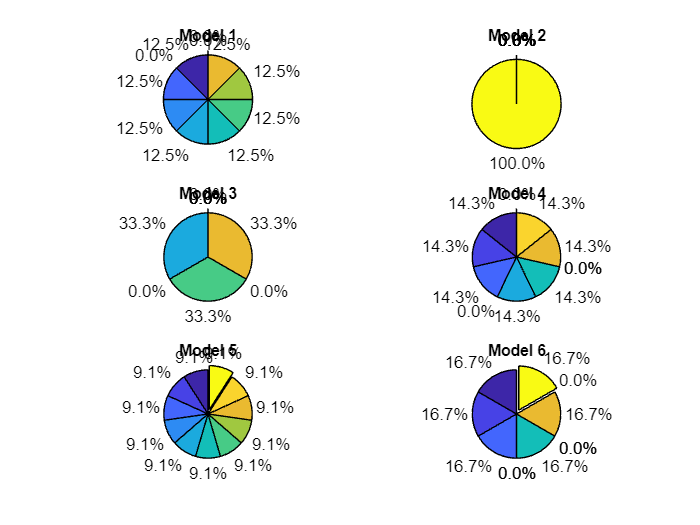

    a1=amp_m1(X,ampl_arr1,amp1_arr2);
    a2=dom_fft_m2(X,dom_fr_fft1,dom_fr_fft2);
    a3=dom_fr_spm3(X,dom_fre_Stft1,dom_fre_Stft2);
    a4=spect_centr_m4(X,Spectral_cent_1,Spectral_cent_2);
    a5=tempo_m5(X,tempo_arr1,tempo_arr2);
    a6=zcr_m6(X,zcr_arr1,zcr_arr2);
    

    a1=a1*10;
    a2=a2*10;
    a3=a3*10;
    a4=a4*10;
    a5=a5*10;
    a6=a6*10;
    

    a=zeros(1,11);
    for i=1:11
        a(i)=a1(i)+a2(i)+a3(i)+a4(i)+a5(i)+a6(i);
    end



labels = {'blues','classical', 'country', 'disco', 'hiphop', 'jazz', 'metal', 'pop', 'reggae', 'rock', 'none'};
explode = [0 0 0 0 0 0 0 0 0 0 1]; % explode the 'none' slice


total_a1 = sum(a1);
percentages_a1 = (a1 / total_a1) * 100;

total_a2 = sum(a2);
percentages_a2 = (a2 / total_a2) * 100;

total_a3 = sum(a3);
percentages_a3 = (a3 / total_a3) * 100;

total_a4 = sum(a4);
percentages_a4 = (a4 / total_a4) * 100;

total_a5 = sum(a5);
percentages_a5 = (a5 / total_a5) * 100;


total_a6 = sum(a6);
percentages_a6 = (a6 / total_a6) * 100;


percentages_a1(isnan(percentages_a1) | isinf(percentages_a1)) = 0;
percentages_a2(isnan(percentages_a2) | isinf(percentages_a2)) = 0;
percentages_a3(isnan(percentages_a3) | isinf(percentages_a3)) = 0;
percentages_a4(isnan(percentages_a4) | isinf(percentages_a4)) = 0;
percentages_a5(isnan(percentages_a5) | isinf(percentages_a5)) = 0;
percentages_a6(isnan(percentages_a6) | isinf(percentages_a6)) = 0;
figure;

subplot(3,2,1);
h1 = pie(percentages_a1, explode, labels);
title('Model 1');
textHandles1 = findobj(h1, 'Type', 'text');
for i = 1:length(textHandles1)
    textHandles1(i).String = sprintf('%.1f%%', percentages_a1(i));
end

subplot(3,2,2);
h2 = pie(percentages_a2, explode, labels);
title('Model 2');
textHandles2 = findobj(h2, 'Type', 'text');
for i = 1:length(textHandles2)
    textHandles2(i).String = sprintf('%.1f%%', percentages_a2(i));
end

subplot(3,2,3);
h3 = pie(percentages_a3, explode, labels);
title('Model 3');
textHandles3 = findobj(h3, 'Type', 'text');
for i = 1:length(textHandles3)
    textHandles3(i).String = sprintf('%.1f%%', percentages_a3(i));
end

subplot(3,2,4);
h4 = pie(percentages_a4, explode, labels);
title('Model 4');
textHandles4 = findobj(h4, 'Type', 'text');
for i = 1:length(textHandles4)
    textHandles4(i).String = sprintf('%.1f%%', percentages_a4(i));
end

subplot(3,2,5);
h5 = pie(percentages_a5, explode, labels);
title('Model 5');
textHandles4 = findobj(h5, 'Type', 'text');
for i = 1:length(textHandles4)
    textHandles4(i).String = sprintf('%.1f%%', percentages_a5(i));
end

subplot(3,2,6);
h6 = pie(percentages_a6, explode, labels);
title('Model 6');
textHandles4 = findobj(h6, 'Type', 'text');
for i = 1:length(textHandles4)
    textHandles4(i).String = sprintf('%.1f%%', percentages_a6(i));
end

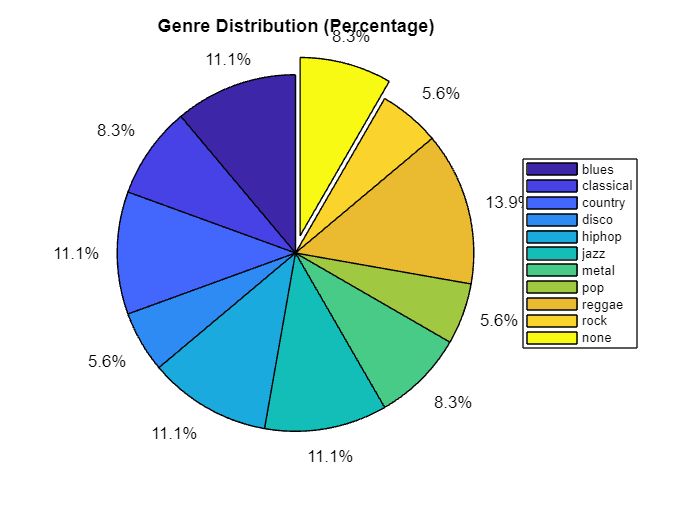


tot=sum(a);

a=a/tot;
a=a*100;
figure;
h = pie(a, explode, labels);
title('Genre Distribution (Percentage)');
legend(labels, 'Location', 'eastoutside', 'FontSize', 8);
% Adjust text properties for each percentage inside the pie
textHandles = findobj(h, 'Type', 'text');
for i = 1:length(textHandles)
    textHandles(i).String = sprintf('%.1f%%', a(i));
end


% Find the top 5 genres
[~, top5_indices] = maxk(a, 5);

%top5_genres = labels(top5_indices);

% Plot pie chart for the top 5 genres
%figure;
%explode_top5 = zeros(1, 5);
%explode_top5 = [0 0 0 0 1];  % Adjust the explode value as needed
%h_top5 = pie(a(top5_indices), explode_top5, labels(top5_indices));
%title('Top 5 Genres');

% Store the names of the top 5 genres
top5_genres = labels(top5_indices);

% Adjust text properties for each percentage inside the pie
legend(labels, 'Location', 'eastoutside', 'FontSize', 8);

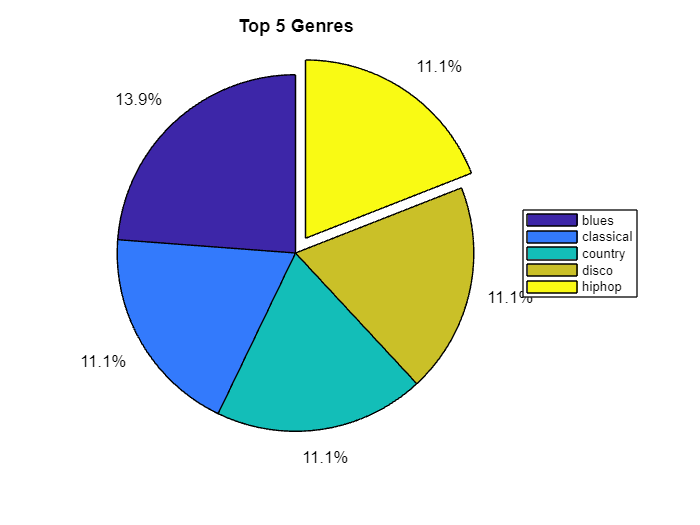

textHandles_top5 = findobj(h_top5, 'Type', 'text');
for i = 1:length(textHandles_top5)
    textHandles_top5(i).String = sprintf('%.1f%%', a(top5_indices(i)));
end

%end




function dominant_frequency_spectogram=spect_dom_freq(y,Fs)
    window_length = 1024; % Adjust window length as needed
    hop_size=512;

    % Calculate STFT
    spectrogram_data = spectrogram(y, window_length, window_length - hop_size);

    % Get frequencies and magnitudes
    frequencies = linspace(0, Fs/2, size(spectrogram_data, 1));
    magnitudes = abs(spectrogram_data);

    % Find the frequency with the highest magnitude for each time frame
    [~, max_idx] = max(magnitudes, [], 1);
    dominant_frequency_idx = frequencies(max_idx);

    % Get the median frequency across all time frames as the dominant frequency
    dominant_frequency_spectogram = median(dominant_frequency_idx);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function amp=amp_fft(y)
    N = length(y); % Length of the signal
    Y = fft(y); % Compute the FFT
    amp=sum(abs(Y))/N;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function dominant_frequency_fft = dom_freq_fft(y,Fs)
    N = length(y); % Length of the signal
    Y = fft(y); % Compute the FFT
    frequencies = (0:N-1) * (Fs / N); % Frequency axis
    
    % Calculate single-sided spectrum
    Y_single_sided = Y(1:N/2+1);
    frequencies_single_sided = frequencies(1:N/2+1);
    
    % Find the frequency with the highest magnitude
    [~, idx] = max(abs(Y_single_sided));
    dominant_frequency_fft = frequencies_single_sided(idx);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function zcr = calculateZCR(y)
    % Ensure that the input signal is a column vector
    if size(y, 2) > 1
        y = y(:, 1);
    end

    % Calculate the zero-crossings
    zero_crossings = sum(abs(diff(y > 0)));

    % Calculate ZCR as the number of zero-crossings divided by the length of the signal
    zcr = zero_crossings / length(y);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function estimatedTempo = calculateTempo(y, Fs)
    % Calculate tempo for the given audio signal

    % Parameters for feature extraction
    windowSize = 1024;
    hopSize = 512;

    % Estimate tempo
    estimatedTempo = estimateTempo(y, Fs, windowSize, hopSize);
    
    
end

function estimatedTempo = estimateTempo(y, Fs, windowSize, hopSize)
    % Estimate tempo from an audio signal

    % Compute onset strength envelope
    onsetEnv = onsetStrengthEnvelope(y, Fs, windowSize, hopSize);
    
    % Find peaks in the onset strength envelope
    [~, peakLocations] = findpeaks(onsetEnv, 'MinPeakDistance', 100);
    
    % Check if there are enough peaks
    if isempty(peakLocations) || numel(peakLocations) < 2
        estimatedTempo = NaN;  % Set to NaN if there are not enough peaks
        return;
    end
    
    % Calculate inter-peak intervals
    interPeakIntervals = diff(peakLocations);
    
    % Estimate tempo in BPM
    estimatedTempo = 60 / median(interPeakIntervals / Fs);
end

function onsetEnv = onsetStrengthEnvelope(y, Fs, windowSize, hopSize)
   
    specFlux = spectralFlux(y, Fs, windowSize, hopSize);
    
    % Smooth the spectral flux using a moving average
    smoothSpecFlux = smoothdata(specFlux, 'movmean', 3);
    
    % Compute onset strength envelope
    onsetEnv = max(0, smoothSpecFlux);
end

function specFlux = spectralFlux(y, Fs, windowSize, hopSize)
    % Calculate spectral flux as a measure of spectral change
    
    % Compute short-time Fourier transform
    stft = spectrogram(y, windowSize, hopSize, windowSize, Fs);
    
    % Calculate magnitude spectrum
    magSpec = abs(stft);
    
    % Calculate spectral flux
    specFlux = sum((magSpec(:, 2:end) - magSpec(:, 1:end-1)).^2);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%







function a1 = amp_m1(X, ampl_arr1, amp1_arr2)
    a1 = zeros(1, 11);
    for i = 1:11
        if (i<11 && X{1} > ampl_arr1{i} && X{1} <= amp1_arr2{i})
            a1(i) = a1(i) + 1;
        end
        if (i==11 && (X{1} > 73.655 || X{1} <= 0.536))
            a1(11) = a1(11) + 1;
        end
    end
end

function a2 = dom_fft_m2(X, dom_fr_fft1, dom_fr_fft2)
    a2 = zeros(1, 11);
    for i = 1:11

         if (i<11 && X{2} > dom_fr_fft1{i} && X{2} <= dom_fr_fft2{i})
             a2(i) = a2(i) + 1;
         end
         if (i==11 && (X{2} > 1388 || X{2} <= 65))
             a2(11) = a2(11) + 1;
         end
    end
end

function a3 = dom_fr_spm3(X, dom_fre_Stft1, dom_fre_Stft2)
    a3 = zeros(1, 11);
    for i = 1:11
        if (i<11 && X{3} > dom_fre_Stft1{i} && X{3} <= dom_fre_Stft2{i})
            a3(i) = a3(i) + 1;
        end
        if (i==11 && (X{3} > 1830 || X{3} <= 88))
            a3(11) = a3(11) + 1;
        end
    end 
end

function a4 = spect_centr_m4(X, Spectral_cent_1, Spectral_cent_2)
    a4 = zeros(1, 11);
    for i = 1:11
        if (i<11 && X{4} > Spectral_cent_1{i} && X{4} <= Spectral_cent_2{i})
            a4(i) = a4(i) + 1;
        end
        if (i==11 && (X{4} > 3635.63 || X{4} <= 428.425))
            a4(11) = a4(11) + 1;
        end
    end
end
function a5 = tempo_m5(X,tempo_arr1,tempo_arr2)
    a5 = zeros(1, 11);
    for i = 1:11
        if (i < 11 && X{5} > tempo_arr1{i} && X{5} <= tempo_arr2{i})
            a5(i) = a5(i) + 1;  
        end
        if (i == 11 && (X{5} > 3635.63 || X{5} <= 428.425))
            a5(11) = a5(11) + 1;  
        end
    end
end



function a6=zcr_m6(X,zcr_arr1,zcr_arr2)
    a6 = zeros(1, 11);
    for i = 1:11
        if (i < 11 && X{6} >zcr_arr1{i} && X{6} <=zcr_arr2{i})
            a6(i) = a6(i) + 1;  
        end
        if (i == 11 && (X{6} > 3635.63 || X{6} <= 428.425))
            a6(11) = a6(11) + 1;  
        end
    end
end